clc;clear
import robo.*

%initial Parameters setting
l0 = 0.6; l1 = 0.43; l2 = 0.21;

theta1 = 62;  theta3 = -105; theta4 = 47; %revolute joint 
theta1_R = deg2rad(theta1); theta3_R = deg2rad(theta3); theta4_R = deg2rad(theta4);

theta2 = 0.5; %位移 prismatic joint 

### 要求：Write a MATLAB script that calculates the transformation matrix gst(θ) for any motion of the manipulator away from the reference configuration, using the product of exponentials formula. Then use this script to calculate the numerical values of the elements of gst(θ)

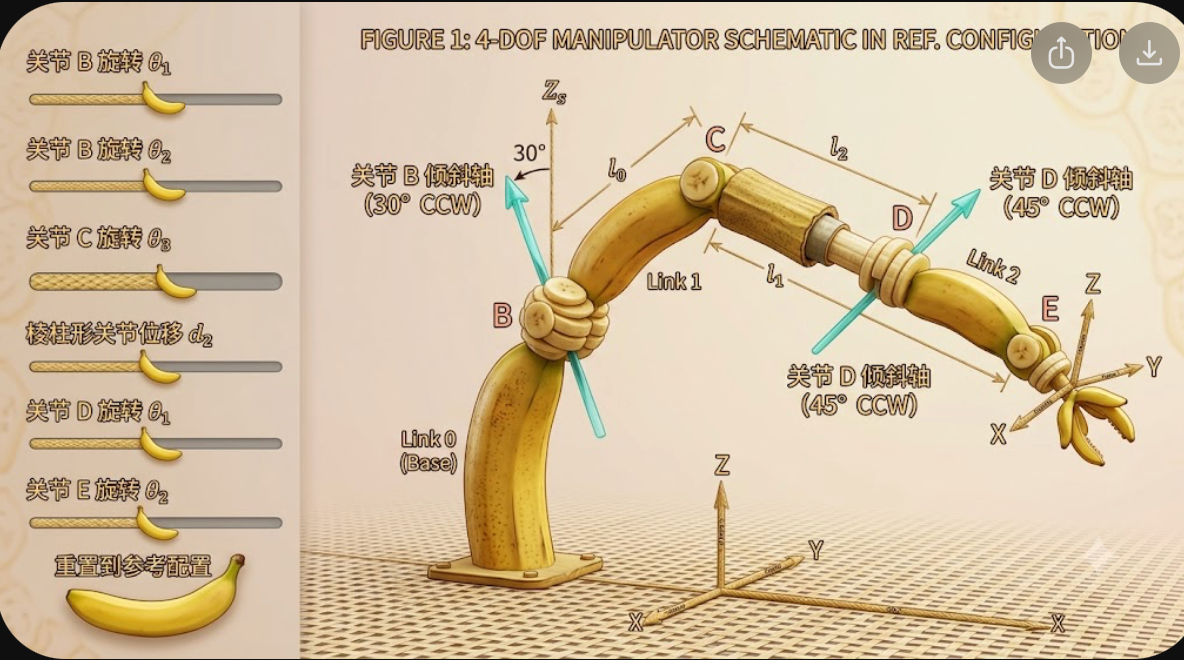

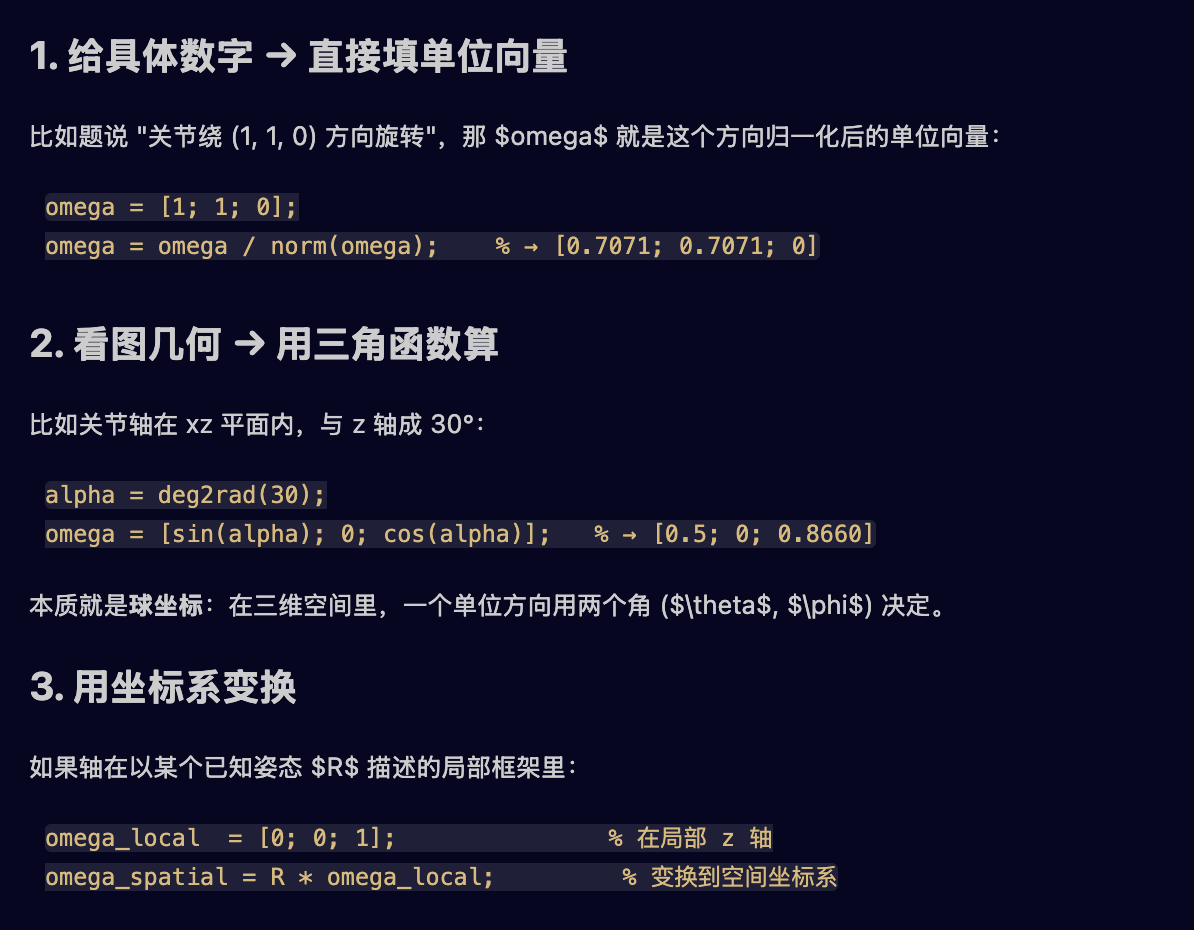

q1 = [0;0;l0]; %joint B  in spatial frame
q3 = [0;l1;l0];%joint CD in spatial frame
q4 = [0;l1+l2;l0]; %joint of tool in spatial frame
d = q3; %这玩意是一个 prismatic joint 所以假设先这样吧
%================
%接下里来表示gst0，tool frame 在spatial frame里的坐标

gst0  =  gmat(eye(3),q4); %用来生成homo的方程（gmat）

omega1 = [0;-sin(pi/6);cos(pi/6)]; %题目里的初始条件关于 joint的旋转是与Z轴成30度角
v2 = [0; 0; 1];                    %题目里面说这个是prismatic joint aling y-z plane
omega3 = [0; -sin(pi/4);cos(pi/4)];%题目里面说这个关于 z轴成45度角逆时针
omega4 = [0; 0; 1];

% 构建xi

xi1 = [-hatm(omega1)*q1;omega1];
xi2 = [v2              ;[0;0;0]];
xi3 = [-hatm(omega3)*q3;omega3];
xi4 = [-hatm(omega4)*q4;omega4];

G1 = gtwist(xi1,theta1_R) %注意这里是输入rad，别整错了

G1 =     0.4695   -0.7647   -0.4415    0.2649
    0.7647    0.6021   -0.2297    0.1378
    0.4415   -0.2297    0.8674    0.0796
         0         0         0    1.0000


G2 = gtwist(xi2,theta2); %这里前面设置了是0.5
G3 = gtwist(xi3,theta3_R)

G3 =    -0.2588    0.6830    0.6830   -0.7035
   -0.6830    0.3706   -0.6294    0.6483
   -0.6830   -0.6294    0.3706    0.6483
         0         0         0    1.0000


G4 = gtwist(xi4,theta4_R)

G4 =     0.6820   -0.7314         0    0.4681
    0.7314    0.6820         0    0.2035
         0         0    1.0000         0
         0         0         0    1.0000



gst = G1 * G2 * G3 * G4 *gst0 %这里不是解IK，所以用gst来表示

gst =     0.7094   -0.2987    0.6383   -0.4834
    0.3425    0.9377    0.0582    0.3309
   -0.6160    0.1773    0.7676    0.8657
         0         0         0    1.0000



R_matrix = gst(1:3,1:3)

R_matrix =     0.7094   -0.2987    0.6383
    0.3425    0.9377    0.0582
   -0.6160    0.1773    0.7676


P_matrix = gst(1:3,4)

P_matrix =    -0.4834
    0.3309
    0.8657



axang = rotm2axang(R_matrix);
omega = axang(1:3)'

omega =     0.0843
    0.8872
    0.4535


v = axang(4)

v = 0.7850

# 尼老师下面给了一个画图的function

%=======================
function ddd = draw_triad(g,n,f)
    % Function to the add triad defined by transformation g (1st input parameter)
    % on existing 3D plot in figure n (2nd input parameter).
    % The length of the triad vectors are reduced by fraction factor f
    %    (3rd parameter)
    % The function returns true if is completes successfully.

    p = g(1:3,4);
    u = g(1:3,1)*f;
    v = g(1:3,2)*f;
    w = g(1:3,3)*f;
    figure(n)
    hold on
    quiver3(p(1),p(2),p(3),u(1),u(2),u(3),'r','linewidth',1.5)
    quiver3(p(1),p(2),p(3),v(1),v(2),v(3),'b','linewidth',1.5)
    quiver3(p(1),p(2),p(3),w(1),w(2),w(3),'g','linewidth',1.5)
    hold off
    ddd = true;
end